TRAJECTORY PLANNING

close all
clear all

% initial model-configuration
x_i = 0;
y_i = 0;
theta_i = 0;

qi = [x_i, y_i, theta_i]'

qi =      0
     0
     0


% final model-configuration
%q_f = rand(1,3)';
%q_f = q_f / norm(q_f)
q_f = [0.5293; 0.4816; 0.6985]

q_f =     0.5293
    0.4816
    0.6985


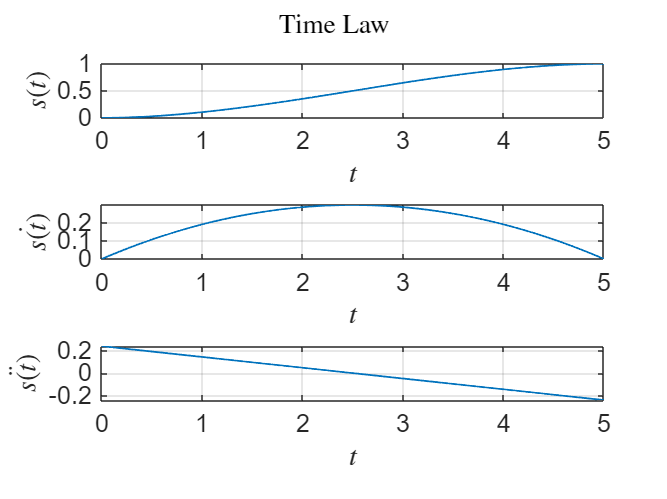


x_f = q_f(1);
y_f = q_f(2);
theta_f = q_f(3);

k = 2;
Tf = 5;
Tc = 0.01;
Ti = 0;
T = Tf-Ti;
t = 0:Tc:Tf;

[s, s_d, s_dd] = cubic_polynomial(T, t);

figure
sgtitle('Time Law','Interpreter','latex') 
subplot(3,1,1)
plot(t,s,'LineWidth',1);
grid("on");
xlabel('$t$','Interpreter','latex')
ylabel('$s(t)$','Interpreter','latex')
set(gca,'Fontsize',14)
subplot(3,1,2)
plot(t,s_d,'LineWidth',1);
grid("on");
xlabel('$t$','Interpreter','latex')
ylabel('$\dot{s(t)}$','Interpreter','latex')
set(gca,'Fontsize',14)
subplot(3,1,3)
plot(t,s_dd,'LineWidth',1);
grid("on");
xlabel('$t$','Interpreter','latex')
ylabel('$\ddot{s(t)}$','Interpreter','latex')
set(gca,'Fontsize',14)
set(gcf, 'PaperPositionMode', 'auto');
exportgraphics(gcf, 'time_law1.pdf', 'BackgroundColor', 'none', 'ContentType', 'vector');

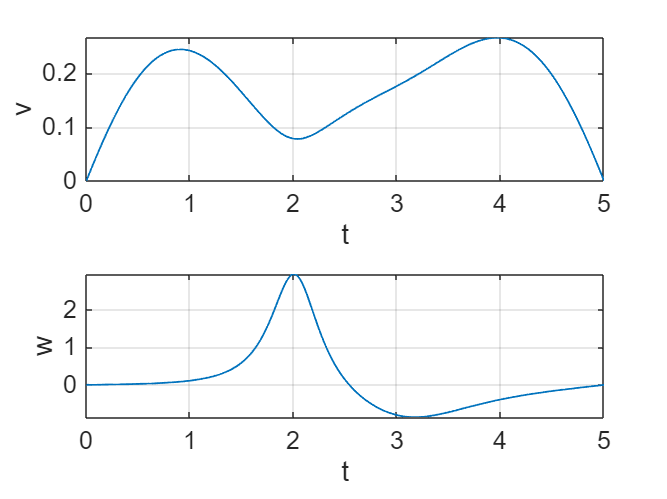



alpha_x = k*cos(theta_f) - 3*x_f;
alpha_y = k*sin(theta_f) - 3*y_f;
beta_x = k*cos(theta_i) + 3*x_i;
beta_y=  k*sin(theta_i) + 3*y_i;

[v_t, w_t, x_s, y_s, theta] = trajectory(s, s_d, s_dd, q_f, qi, alpha_x, alpha_y, beta_x, beta_y);

figure
subplot(2,1,1)
plot(t,v_t,'lineWidth',1)
xlabel('t')
ylabel('v')
set(gca,'Fontsize',14)
grid("on")
xlim([0, Tf])
hold on
subplot(2,1,2)
plot(t,w_t,'lineWidth',1)
xlabel('t')
ylabel('w')
set(gca,'Fontsize',14)
grid("on")
xlim([0, Tf])
set(gcf, 'PaperPositionMode', 'auto');
exportgraphics(gcf, 'v_w.pdf', 'BackgroundColor', 'none', 'ContentType', 'vector');

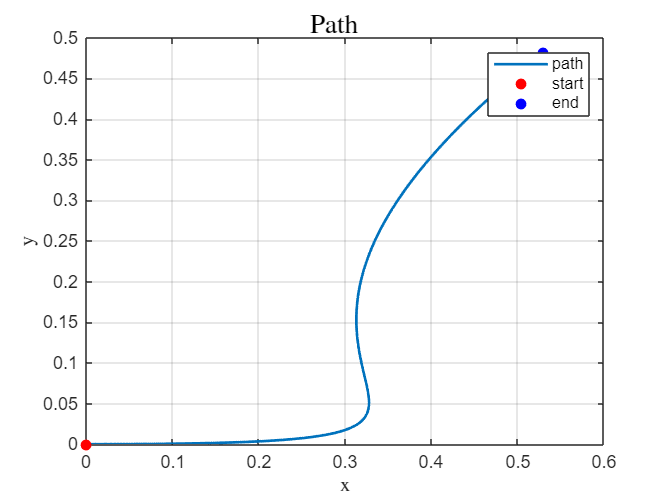


figure
sgtitle('Path','Interpreter','latex') 
plot(x_s,y_s,'lineWidth',1.5)
xlabel('x','Interpreter','latex')
ylabel('y','Interpreter','latex')
hold on 
scatter(x_s(1),y_s(1),'red','filled','o')
hold on 
scatter(x_s(end),y_s(end),'blue','filled','o')
grid("on");
legend('path','start','end' )
set(gcf, 'PaperPositionMode', 'auto');
exportgraphics(gcf, 'path.pdf', 'BackgroundColor', 'none', 'ContentType', 'vector');

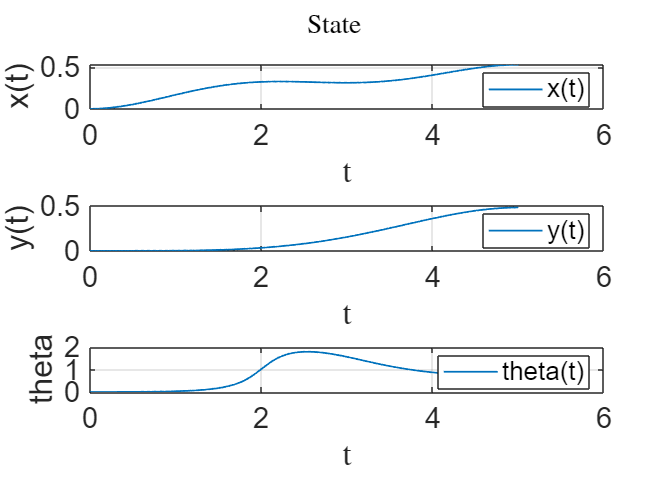


figure
sgtitle('State','Interpreter','latex') 
subplot(3,1,1)
plot(t,x_s,'lineWidth',1)
xlabel('t','Interpreter','latex')
ylabel('x(t)')
set(gca,'Fontsize',16)
grid("on")
legend('x(t)')
hold on 
subplot(3,1,2)
plot(t,y_s,'lineWidth',1)
xlabel('t','Interpreter','latex')
ylabel('y(t)')
set(gca,'Fontsize',16)
grid("on")
legend('y(t)')
hold on
subplot(3,1,3)
plot(t,theta,'lineWidth',1)
xlabel('t','Interpreter','latex')
ylabel('theta')
set(gca,'Fontsize',16)
grid("on")
legend('theta(t)')
set(gcf, 'PaperPositionMode', 'auto');
exportgraphics(gcf, 'states.pdf', 'BackgroundColor', 'none', 'ContentType', 'vector');

v_max = 0.5; 
w_max = 2;  
Tf = 5;
t = 0:Tc:Tf;
[s, s_d, s_dd] = cubic_polynomial(Tf, t);
[v_t, w_t, x_s, y_s, theta] = trajectory(s, s_d, s_dd, q_f, qi, alpha_x, alpha_y, beta_x, beta_y);
% Verifica se i limiti di velocità sono soddisfatti
if max(abs(v_t)) <= v_max && max(abs(w_t)) <= w_max
    disp('Velocity bounds are satisfied.')
    scaling = false;
else
    disp('Velocity bounds are NOT satisfied.')
    T_min = Tf;               % Inizialmente è il nostro candidato
    scaling = true;
    max_iter = 150;
    iter = 0;

    while iter < max_iter

        iter = iter + 1;   
        Tn = Tc * Tf;         
        t = 0:Tn:Tf;
        T = Tf;

        [s, s_d, s_dd] = cubic_polynomial(T, t);

        [v_t, w_t, x_s, y_s, theta] = trajectory(s, s_d, s_dd, q_f, qi, alpha_x, alpha_y, beta_x, beta_y);

        if max(abs(v_t)) <= v_max && max(abs(w_t)) <= w_max
            disp('Velocity bounds satisfied.');
            T_min = Tf;
        break;
    else
        disp(['Iteration ', num2str(iter), ': velocity limits NOT satisfied. Increasing Tf...']);
        Tf = Tf + 0.1;
        disp(['Tf = ', num2str(Tf)]);
        end
    end
end

Velocity bounds are NOT satisfied.


Iteration 1: velocity limits NOT satisfied. Increasing Tf...


Tf = 5.1


Iteration 2: velocity limits NOT satisfied. Increasing Tf...


Tf = 5.2


Iteration 3: velocity limits NOT satisfied. Increasing Tf...


Tf = 5.3


Iteration 4: velocity limits NOT satisfied. Increasing Tf...


Tf = 5.4


Iteration 5: velocity limits NOT satisfied. Increasing Tf...


Tf = 5.5


Iteration 6: velocity limits NOT satisfied. Increasing Tf...


Tf = 5.6


Iteration 7: velocity limits NOT satisfied. Increasing Tf...


Tf = 5.7


Iteration 8: velocity limits NOT satisfied. Increasing Tf...


Tf = 5.8


Iteration 9: velocity limits NOT satisfied. Increasing Tf...


Tf = 5.9


Iteration 10: velocity limits NOT satisfied. Increasing Tf...


Tf = 6


Iteration 11: velocity limits NOT satisfied. Increasing Tf...


Tf = 6.1


Iteration 12: velocity limits NOT satisfied. Increasing Tf...


Tf = 6.2


Iteration 13: velocity limits NOT satisfied. Increasing Tf...


Tf = 6.3


Iteration 14: velocity limits NOT satisfied. Increasing Tf...


Tf = 6.4


Iteration 15: velocity limits NOT satisfied. Increasing Tf...


Tf = 6.5


Iteration 16: velocity limits NOT satisfied. Increasing Tf...


Tf = 6.6


Iteration 17: velocity limits NOT satisfied. Increasing Tf...


Tf = 6.7


Iteration 18: velocity limits NOT satisfied. Increasing Tf...


Tf = 6.8


Iteration 19: velocity limits NOT satisfied. Increasing Tf...


Tf = 6.9


Iteration 20: velocity limits NOT satisfied. Increasing Tf...


Tf = 7


Iteration 21: velocity limits NOT satisfied. Increasing Tf...


Tf = 7.1


Iteration 22: velocity limits NOT satisfied. Increasing Tf...


Tf = 7.2


Iteration 23: velocity limits NOT satisfied. Increasing Tf...


Tf = 7.3


Iteration 24: velocity limits NOT satisfied. Increasing Tf...


Tf = 7.4


Velocity bounds satisfied.


disp(['Minimum time found: Tf = ', num2str(T_min)]);

Minimum time found: Tf = 7.4


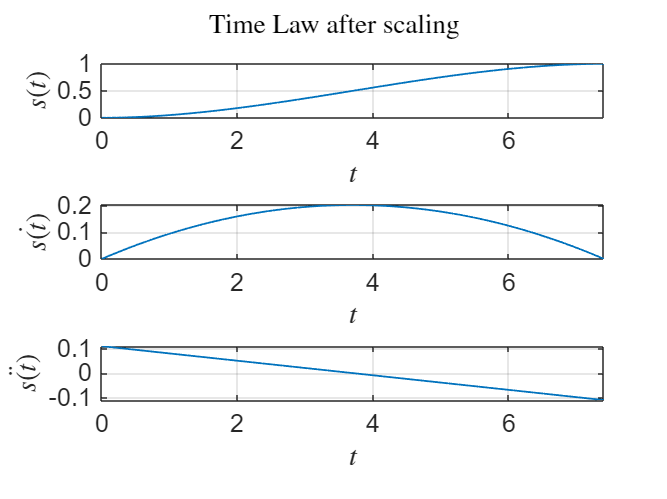


figure
sgtitle('Time Law after scaling','Interpreter','latex')
subplot(3,1,1)
plot(t,s,'LineWidth',1);
grid("on");
xlabel('$t$','Interpreter','latex')
ylabel('$s(t)$','Interpreter','latex')
set(gca,'Fontsize',14)
xlim([0, Tf])
subplot(3,1,2)
plot(t,s_d,'LineWidth',1);
grid("on");
xlabel('$t$','Interpreter','latex')
ylabel('$\dot{s(t)}$','Interpreter','latex')
set(gca,'Fontsize',14)
xlim([0, Tf])
subplot(3,1,3)
plot(t,s_dd,'LineWidth',1);
grid("on");
xlabel('$t$','Interpreter','latex')
ylabel('$\ddot{s(t)}$','Interpreter','latex')
set(gca,'Fontsize',14)
xlim([0, Tf])
set(gcf, 'PaperPositionMode', 'auto');
exportgraphics(gcf, 'time_law_scal.pdf', 'BackgroundColor', 'none', 'ContentType', 'vector');

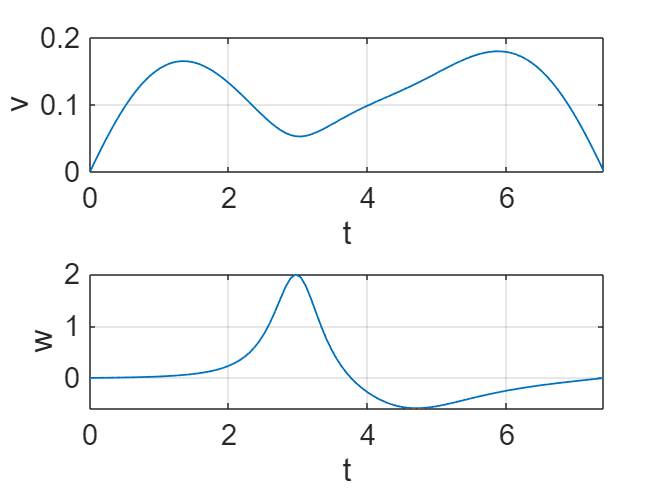



figure
subplot(2,1,1)
plot(t,v_t,'lineWidth',1)
xlabel('t')
ylabel('v')
set(gca,'Fontsize',16)
grid("on")
xlim([0, Tf])
hold on
subplot(2,1,2)
plot(t,w_t,'lineWidth',1)
xlabel('t')
ylabel('w')
set(gca,'Fontsize',16)
grid("on")
xlim([0, Tf])
set(gcf, 'PaperPositionMode', 'auto');
exportgraphics(gcf, 'v_w_scal.pdf', 'BackgroundColor', 'none', 'ContentType', 'vector');

## INPUT / OUTPUT LINEARIZATION

b1 = 0.05;
b2 = 0.1;
b3 = 0.2;
b4 = 0.3;
b5 = 0.5;
b6 = 0.6;
b_values = [b1 b2 b3 b4 b5 b6];

k1 = 10;
k2 = 10;


xd_all = zeros(length(b_values), length(t));   
yd_all = zeros(length(b_values), length(t));
thetad_all = zeros(length(b_values), length(t));
x_sim_all = zeros(length(b_values), length(t));   
y_sim_all = zeros(length(b_values), length(t));
theta_sim_all = zeros(length(b_values), length(t));
y1d_all = zeros(length(b_values),length(t));
y2d_all = zeros(length(b_values),length(t));
ddxd_all = zeros(length(b_values),length(t));
y1_all = zeros(length(b_values),length(t));
y2_all = zeros(length(b_values),length(t));
y1_dot_d_all = zeros(length(b_values),length(t));
y2_dot_d_all = zeros(length(b_values),length(t));
wd_all = zeros(length(b_values),length(t));
ex_all = zeros(length(b_values), length(t));   
ey_all = zeros(length(b_values), length(t));
etheta_all = zeros(length(b_values), length(t));
v_all = zeros(length(b_values), length(t));
w_all = zeros(length(b_values), length(t));
u1_all = zeros(length(b_values), length(t));
u2_all = zeros(length(b_values), length(t));

for bb = 1:6
    b = b_values(bb);

    y1d_all(bb,:) = x_s + b*cos(theta);
    y2d_all(bb,:) = y_s + b*sin(theta);
    y1_dot_d_all(bb,:) = cos(theta).*v_t - b*sin(theta).*w_t;
    y2_dot_d_all(bb,:) = sin(theta).*v_t + b*cos(theta).*w_t;


    y1_des = timeseries(y1d_all(bb,:),t);
    y2_des = timeseries(y2d_all(bb,:),t); 
    y1_dot_des = timeseries(y1_dot_d_all(bb,:),t); 
    y2_dot_des = timeseries(y2_dot_d_all(bb,:),t); 
    
    theta_des = timeseries(theta,t);
    x_des = timeseries(x_s,t); 
    y_des = timeseries(y_s,t); 


    out = sim('input_output_feedback.slx');
    x_sim_all(bb,:) = out.x_sim.data;
    y_sim_all(bb,:) = out.y_sim.data;
    theta_sim_all(bb,:) = out.theta_sim.data;

    ex_all(bb,:) = out.ex.data;
    ey_all(bb,:) = out.ey.data;
    etheta_all(bb,:) = out.etheta.data;
    
    y1_all(bb,:) = out.y1_sim.data;
    y2_all(bb,:) = out.y2_sim.data;

    v_all(bb,:) = out.v.data;
    w_all(bb,:) = out.w.data;
    u1_all(bb,:) = out.u1.data;
    u2_all(bb,:) = out.u2.data;
    
end

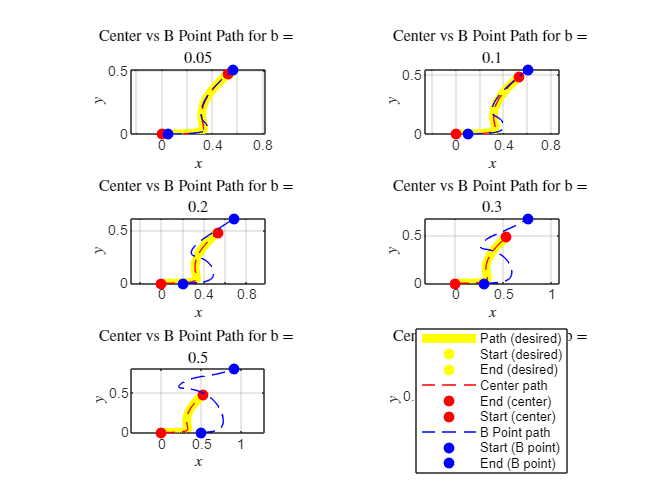

figure
for bb = 1:6
    subplot(3,2,bb)
    plot(x_s,y_s,'y','lineWidth', 5, 'DisplayName', 'Path (desired)');
    hold on
    scatter(x_s(1),y_s(1),'y','filled','o', 'DisplayName', 'Start (desired)') 
    scatter(x_s(end),y_s(end),'y','filled','o', 'DisplayName', 'End (desired)')
    plot(x_sim_all(bb,:), y_sim_all(bb,:),'red--', 'LineWidth', 0.5, 'DisplayName', 'Center path');
    scatter(x_sim_all(bb,end), y_sim_all(bb,end), 'red', 'filled', 'DisplayName', 'End (center)');
    scatter(x_sim_all(bb,1), y_sim_all(bb,1), 'red', 'filled', 'DisplayName', 'Start (center)');
    plot(y1_all(bb,:), y2_all(bb,:),'b--', 'LineWidth', 0.5, 'DisplayName', 'B Point path');
    scatter(y1_all(bb,1), y2_all(bb,1), 'b', 'filled', 'DisplayName', 'Start (B point)');
    scatter(y1_all(bb,end), y2_all(bb,end), 'b', 'filled', 'DisplayName', 'End (B point)');
    xlabel('$x$','Interpreter','latex')
    ylabel('$y$','Interpreter','latex')
    grid on
    axis equal
    title('Center vs B Point Path for b = ',num2str(b_values(bb)),'Interpreter','latex')
end
legend('Location','best')
set(gcf, 'PaperPositionMode', 'auto');
exportgraphics(gcf, 'center_b_path.pdf', 'BackgroundColor', 'none', 'ContentType', 'vector');

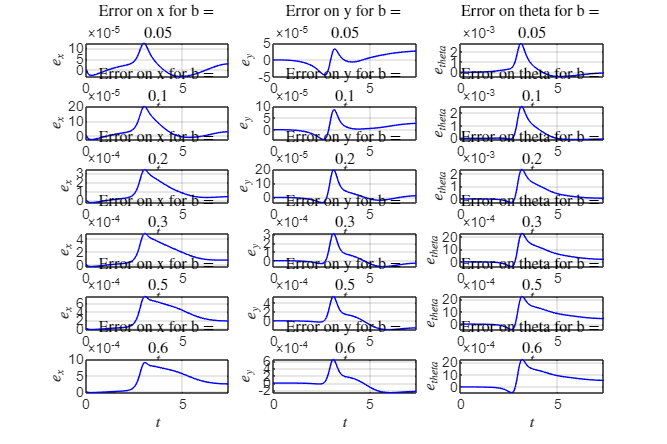


figure('Units','normalized','Position',[0 0 1 1])  
for bb = 1:6
    subplot(6,3,(bb-1)*3+1)
    plot(t,ex_all(bb,:),'b','lineWidth', 0.5);
    title('Error on x for b = ',num2str(b_values(bb)),'Interpreter','latex')
    grid on
    xlabel('$t$','Interpreter','latex')
    ylabel('$e_{x}$','Interpreter','latex')
    xlim([0, Tf])

    subplot(6,3,(bb-1)*3+2)
    plot(t,ey_all(bb,:),'b','lineWidth', 0.5);
    title('Error on y for b = ',num2str(b_values(bb)),'Interpreter','latex')
    grid on
    xlabel('$t$','Interpreter','latex')
    ylabel('$e_{y}$','Interpreter','latex')
    xlim([0, Tf])

    subplot(6,3,(bb-1)*3+3)
    plot(t,etheta_all(bb,:),'b','lineWidth', 0.5);
    title('Error on theta for b = ',num2str(b_values(bb)),'Interpreter','latex')
    xlabel('$t$','Interpreter','latex')
    ylabel('$e_{theta}$','Interpreter','latex')
    grid on
    xlim([0, Tf])
end
set(gcf, 'PaperPositionMode', 'auto');
exportgraphics(gcf, 'error_1_2.pdf', 'BackgroundColor', 'none', 'ContentType', 'vector');

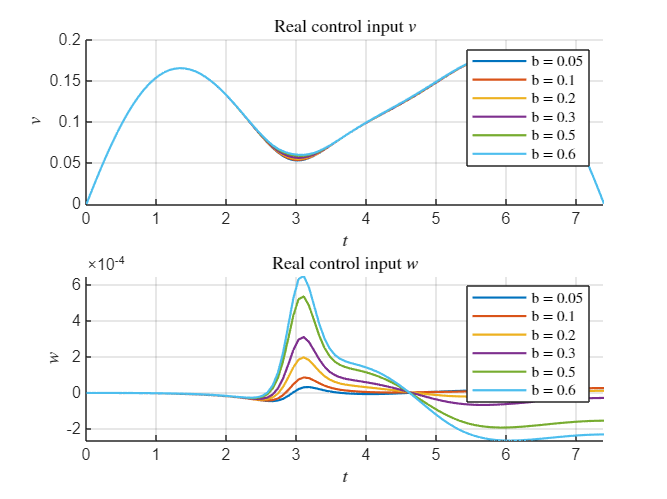


figure 
subplot(2,1,1)
hold on
for bb = 1:6
    plot(t, v_all(bb,:), 'LineWidth', 1.2, ...
         'DisplayName', ['b = ', num2str(b_values(bb))]);
end
title('Real control input $v$', 'Interpreter','latex')
xlabel('$t$', 'Interpreter','latex')
ylabel('$v$','Interpreter','latex')
grid on
xlim([0, Tf])
legend('Interpreter','latex')
subplot(2,1,2)
hold on
for bb = 1:6
    plot(t, ey_all(bb,:), 'LineWidth', 1.2, ...
         'DisplayName', ['b = ', num2str(b_values(bb))]);
end
title('Real control input $w$', 'Interpreter','latex')
xlabel('$t$', 'Interpreter','latex')
ylabel('$w$','Interpreter','latex')
grid on
xlim([0, Tf])
legend('Interpreter','latex')
set(gcf, 'PaperPositionMode', 'auto');
exportgraphics(gcf, 'v_w_1_2.pdf', 'BackgroundColor', 'none', 'ContentType', 'vector');

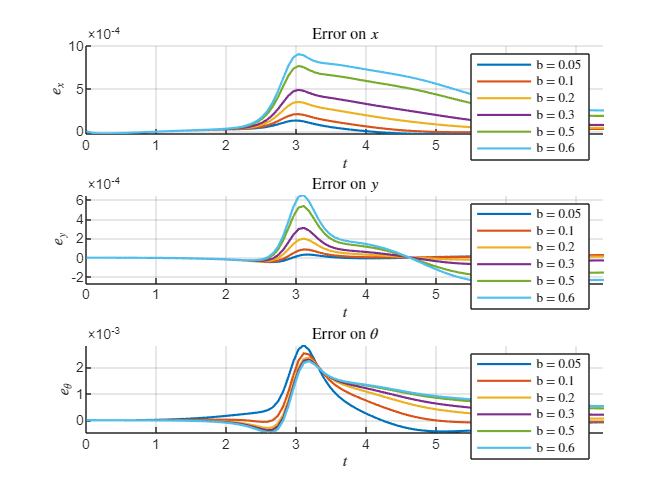



figure 
subplot(3,1,1)
hold on
for bb = 1:6
    plot(t, ex_all(bb,:), 'LineWidth', 1.2, ...
         'DisplayName', ['b = ', num2str(b_values(bb))]);
end
title('Error on $x$', 'Interpreter','latex')
xlabel('$t$', 'Interpreter','latex')
ylabel('$e_{x}$','Interpreter','latex')
grid on
xlim([0, Tf])
legend('Interpreter','latex')
subplot(3,1,2)
hold on
for bb = 1:6
    plot(t, ey_all(bb,:), 'LineWidth', 1.2, ...
         'DisplayName', ['b = ', num2str(b_values(bb))]);
end
title('Error on $y$', 'Interpreter','latex')
xlabel('$t$', 'Interpreter','latex')
ylabel('$e_{y}$','Interpreter','latex')
grid on
xlim([0, Tf])
legend('Interpreter','latex')
subplot(3,1,3)
hold on
for bb = 1:6
    plot(t, etheta_all(bb,:), 'LineWidth', 1.2, ...
         'DisplayName', ['b = ', num2str(b_values(bb))]);
end
title('Error on $\theta$', 'Interpreter','latex')
xlabel('$t$', 'Interpreter','latex')
ylabel('$e_{\theta}$','Interpreter','latex')
grid on
xlim([0, Tf])
legend('Interpreter','latex')

set(gcf, 'PaperPositionMode', 'auto');
exportgraphics(gcf, 'error_comp_1_2.pdf', 'BackgroundColor', 'none', 'ContentType', 'vector');

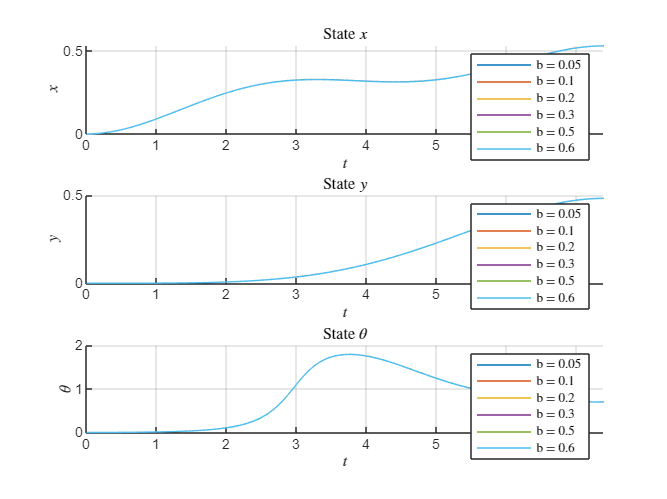


figure 
subplot(3,1,1)
hold on
for bb = 1:6
    plot(t, x_sim_all(bb,:), 'LineWidth', 0.1, ...
         'DisplayName', ['b = ', num2str(b_values(bb))]);
end
title('State $x$', 'Interpreter','latex')
xlabel('$t$', 'Interpreter','latex')
ylabel('$x$','Interpreter','latex')
grid on
xlim([0, Tf])
legend('Interpreter','latex')
subplot(3,1,2)
hold on
for bb = 1:6
    plot(t, y_sim_all(bb,:), 'LineWidth', 0.1, ...
         'DisplayName', ['b = ', num2str(b_values(bb))]);
end
title('State $y$', 'Interpreter','latex')
xlabel('$t$', 'Interpreter','latex')
ylabel('$y$','Interpreter','latex')
grid on
xlim([0, Tf])
legend('Interpreter','latex')
subplot(3,1,3)
hold on
for bb = 1:6
    plot(t, theta_sim_all(bb,:), 'LineWidth', 0.1, ...
         'DisplayName', ['b = ', num2str(b_values(bb))]);
end
title('State $\theta$', 'Interpreter','latex')
xlabel('$t$', 'Interpreter','latex')
ylabel(' $\theta$','Interpreter','latex')
grid on
xlim([0, Tf])
legend('Interpreter','latex')

set(gcf, 'PaperPositionMode', 'auto');
exportgraphics(gcf, 'states_1_2.pdf', 'BackgroundColor', 'none', 'ContentType', 'vector');